close all;
clear;
clc;

% planning path
% % shape I
% t=1:100;
% rou0=0+t*1;
% fai0=pi/4+t*0;

% % shape O
% t=-0.49*pi:0.01*pi:0.5*pi;
% rou0=2*10*cos(t);
% fai0=t;

% shape S
% t=0.01:0.02*pi:2*pi;
% rou0=sqrt(t.*t+sin(t).*sin(t));
% fai0=atan(sin(t)./t);

% % shape 8
% a=2;
% t=0.01:0.02*pi:2*pi;
% x=-a+a.*cos(t)./(1+sin(t).^2);
% y=a.*sin(t).*cos(t)./(1+sin(t).^2);
% rou0=sqrt(x.^2+y.^2);
% fai0=atan(y./x);

% % shape SmartLake
SmartLake=csvread('TJlake.csv');
rou0=0.05*(sqrt(SmartLake(:,1).^2+SmartLake(:,2).^2))';
fai0=(atan(SmartLake(:,2)./SmartLake(:,1)))';

TJ=[fai0;rou0];
LTJ=length(TJ);
%planning path

% normal distribution of wind current and wave
zt0=normrnd(1.00,0.44,1,LTJ);
cr0=normrnd(0.25,0.11,1,LTJ);
wd0=normrnd(7.80,2.53,1,LTJ);

% new distribution of wind current and wave
wd1=sort(wd0);
b1=size(wd1,2);
wd11=[];
wd12=[];
for i=1:2:b1
    wd11=[wd11,wd1(i)];
    wd12=[wd12,wd1(i+1)];
end
wd122=sort(wd12,'descend');
wd=[wd11,wd122];
wd_dot=[];
for j=1:b1-1
    wd_dot=[wd_dot,(wd(j+1)-wd(j))/0.01];
end
% wd_dot=[wd(1)/0.01,wd_dot];
% wind speed normal distribution
% current speed normal (chi-square) distribution
cr1=sort(cr0);
b2=size(cr1,2);
cr11=[];
cr12=[];
for i=1:2:b2
    cr11=[cr11,cr1(i)];
    cr12=[cr12,cr1(i+1)];
end
cr122=sort(cr12,'descend');
cr=[cr11,cr122];
cr_dot=[];
for j=1:b2-1
    cr_dot=[cr_dot,(cr(j+1)-cr(j))/0.01];
end
% cr_dot=[cr(1)/0.01,cr_dot];
% current speed normal (chi-square) distribution
% wave parameter normal distribution
zt1=sort(zt0);
b3=size(zt1,2);
zt11=[];
zt12=[];
for i=1:2:b3
    zt11=[zt11,zt1(i)];
    zt12=[zt12,zt1(i+1)];
end
zt122=sort(zt12,'descend');
zt=[zt11,zt122];
zt_dot=[];
for j=1:b3-1
    zt_dot=[zt_dot,(zt(j+1)-zt(j))/0.01];
end
% zt_dot=[zt(1)/0.01,zt_dot];
alfa=0.7;  %海风舷角rad
beta=0.7;  %海流入射角rad
khai=0.7;  %海浪遭遇角，艏向零度顺时针gm2增加，流力完全推动船舶gm2=0或者2*pi
 lmd=0.2;  %海浪波长

  g = 9.81;       %重力加速度m/s^2
  L = 1.70;      %垂线间长m
Rar = 1.29;     %空气密度约为1.29Kg/m^3
Rwt = 1040;     %海水密度一般在1020～1070 kg/m^3之间

Cxwd=0.6; Axwd=0.13;  %纵向风阻系数和水线上面积
Cywd=0.8; Aywd=0.20;  %横向风阻系数和水线上面积
Cnwd=0.5; Anwd=0.35;  %艏摇方向风阻系数和水线上面积

Cxcr=0.3; Axcr=0.13;  %纵向流阻系数和水线下面积
Cycr=0.7; Aycr=0.31;  %横向流阻系数和水线下面积
Cncr=0.5; Ancr=0.66;  %艏摇方向流阻系数和水线下面积

Wu0=(Axcr*Cxcr*Rwt*abs(cos(beta))*cos(beta)*cr.^2)/2 + (Axwd*Cxwd*Rar*abs(cos(alfa))*cos(alfa)*wd.^2)/2 - (L*Rwt*g*cos(khai)*((51*lmd^3)/800 - (3*lmd^2)/16 + lmd/10 - (1/20))*zt.^2)/2;
Wv0=(Aycr*Cycr*Rwt*abs(sin(beta))*sin(beta)*cr.^2)/2 + (Aywd*Cywd*Rar*abs(sin(alfa))*sin(alfa)*wd.^2)/2 - (L*Rwt*g*sin(khai)*(- (221*lmd^3)/200 + (389*lmd^2)/100 + (683*lmd)/200 - (23/50))*zt.^2)/2;
Wr0=(Ancr*Cncr*Rwt*abs(sin(beta))*sin(beta)*cr.^2)/2 + (Anwd*Cnwd*Rar*abs(sin(alfa))*sin(alfa)*wd.^2)/2 + (L*Rwt*g*sin(khai)*((21*lmd^3)/800 - (79*lmd^2)/400 + (17*lmd)/50 - (11/100))*zt.^2)/2;

Wu0=zeros(1,LTJ);
Wv0=zeros(1,LTJ);
Wr0=zeros(1,LTJ);

% initial state and control
%%%%%%fossen ship model
% uk=(1-d11*T/m11)*u+2*m22*T/m11*v*r+T/m11*Wu+T/m11*taou;
% vk=(1-d22*T/m22)*v-2*m11*T/m22*u*r+T/m22*Wv;
% rk=(1-d33*T/m33)*r+2*(m11-m22)*T/m33*u*v+T/m33*Wr+T/m33*taor;

% puk=(1-d11*T/m11)*pu+2*m22*T*T/m11*v*r+T*T/m11*Wu+T*T/m11*taou;
% pvk=(1-d22*T/m22)*pv-2*m11*T*T/m22*u*r+T*T/m22*Wv;
% prk=(1-d33*T/m33)*pr+2*(m11-m22)*T*T/m33*u*v+T*T/m33*Wr+T*T/m33*taor;
%%%%%fossen ship model

p=5;            %预测步长
T=0.01;         %采样周期 s
u=10;
v=0;
r=0;          %状态变量
pu=u*T;
pv=v*T;
pr=r*T;
rou=sqrt(pu*pu+pv*pv);
Wu=0;
Wv=0;
Wr=0;
taou0=100000;
taou=0;
taor=0;

% m=115.11;
% Iz=26.36;
m=23.8000;
Iz=1.7600;
err_model=0;
Xdu=-2.0*(1+err_model);
Ydv=-10.0*(1+err_model);
Ndr=-1.0*(1+err_model);
Xu=-0.7225*(1+err_model);
Yv=-0.8612*(1+err_model);
Nr=-1.90*(1+err_model);
Xuu=-1.3274*(1+err_model);
Yvv=-36.2823*(1+err_model);
Nrr=-0.75*(1+err_model);
m11=m-Xdu;
m22=m-Ydv;
m33=Iz-Ndr;
% initial state and control

for kk=1:LTJ
    Wu=Wu0(kk);
    Wv=Wv0(kk);
    Wr=Wr0(kk);
    d11=-(Xu+Xuu*abs(u)); 
    d22=-(Yv+Yvv*abs(v)); 
    d33=-(Nr+Nrr*abs(r));
    a1=(1-d11*T/m11);
    a2=2*m22*T*T/m11*v*r+T*T/m11*Wu;
    a3=T*T/m11;
    b1=(1-d22*T/m22);
    b2=-2*m11*T*T/m22*u*r+T*T/m22*Wv;
    b3=T*T/m22;
    c1=(1-d33*T/m33);
    c2=2*(m11-m22)*T*T/m33*u*v+T*T/m33*Wr;
    c3=T*T/m33;
    % puk=a1*pu+a2+a3*taou;
    % pvk=b1*pv+b2;
    % prk=c1*pr+c2+c3*taor;
    %fossen ship model
    
    % prediction function
    Ap1=[];
    Ap2=[];
    Bp1=[];
    Bp2=[];
    Cp1=[];
    Cp2=[];
    for i=1:p
        Ap1=[Ap1;a1^i];
        Ap2=[Ap2;(1-a1^i)/(1-a1)];
        Bp1=[Bp1;b1^i];
        Bp2=[Bp2;(1-b1^i)/(1-b1)];
        Cp1=[Cp1;c1^i];
        Cp2=[Cp2;(1-c1^i)/(1-c1)];
    end
    Ap3=Ap2;
    Bp3=Bp2;
    Cp3=Cp2;
    faip=Cp1*pr(:,kk)+Cp2*c2+Cp3*c3*taor;
    pup=Ap1*pu(:,kk)+Ap2*a2+Ap3*a3*taou;
    pvp=Bp1*pv(:,kk)+Bp2*b2;
    rrp=pup.*pup+pvp.*pvp;
    roup=sqrt(rrp);
    % prediction function
    
    % p by p point follow rou and fai 
    if kk<=(LTJ-p+1)
        j=kk;
    else
        j=(LTJ-p+1);
    end
    Tr=[];
    Tf=[];
    for i1=j:(j+p-1)
        Tr=[Tr;TJ(2,i1)];
        Tf=[Tf;TJ(1,i1)];
    end
    Trr=Tr.*Tr;
    % p by p point follow rou and fai 
    Trr1=TJ(2,kk)*TJ(2,kk);
    Q=1;
    R=0.0001;
    puc=pu(kk);
    pvc=pv(kk);

    aa=-a3^2;
    bb=-2*a3*(a2 + a1*puc);
    cc=Trr1 - (a2 + a1*puc)^2 - (b2 + b1*pvc)^2;
    fun=@(taou) Q*exp(aa*taou^2 + bb*taou +cc)+R*taou^2;
    nonlcon = @(taou) taounonl(taou,aa,bb,cc);
    options=[];
    Ar=[];
    br=[];
    Aeqr=[];
    beqr=[];
    ubr=[]; % 控制量U的上、下限
    lbr=[];
    [taou,fval,exitflag,output]=fmincon(fun,taou0,Ar,br,Aeqr,beqr,lbr,ubr,nonlcon,options)  
    
    if taou<2.0e+5&&kk<10
        taou=1.5e+5;
    else
        taou=taou;
    end

    taou0 = taou;
    taouk(:,kk) = taou;
    pu(:,kk+1)=a1*pu(:,kk)+a2+a3*taou;
    pv(:,kk+1)=b1*pv(:,kk)+b2;
    rou(:,kk+1)=sqrt(pu(:,kk+1)*pu(:,kk+1)+pv(:,kk+1)*pv(:,kk+1));
    
    % optimization of rou
    % syms  Cp1 Cp2 Cp3 pr c2 c3 taor Wr Q3 R3 Tf
    % faip=Cp1*pr+Cp2*c2+Cp3*c3*taor;
    % J2=R3*c3*c3*taor*taor;
    % J1=(faip-Tf)'*Q3*(faip-Tf)
    % J3=J1+J2;
    % J4=(Cp3'*Q3*Cp3+R3)*c3*c3*taor*taor+2*(Cp1*pr+Cp2*c2-Tf)'*Q3*Cp3*c3*taor+(Cp1*pr+Cp2*c2-Tf)'*Q3*(Cp1*pr+Cp2*c2-Tf);
    % collect(J3,taor)
    % collect(J4,taor)

    %%优化目标函数min{1/2*x′Hx+f′x+D}
    Q3=100*eye(size(Cp3,1)); 
    R3=100*eye(size(taor,1));  % 优化目标参数，加权矩阵      
    Ad=[];
    bd=[];
    Aed=[]; % 10000*ones(5,1);
    bed=[]; % -10000*ones(5,1);
    ubd=[]; % 控制量U的上、下限
    lbd=[];
    %Wr1=Wr(kk);
    Hd=2*(Cp3'*Q3*Cp3+R3)*c3*c3;
    fd=2*(Cp1*pr(:,kk)+Cp2*c2-Tf)'*Q3*Cp3*c3;
    % 优化目标函数min{1/2*x′Hx+f′x+D}的矩阵f
    [taor,fvald,exitflagd,outputd,lambdad]=quadprog(Hd,fd',Ad,bd,Aed,bed,lbd,ubd);
    % taor=1*rand(1);
    % taor=-fd/Hd;%-b/2a;
    taork(:,kk) = taor;
    pr(:,kk+1)=c1*pr(:,kk)+c2+c3*taor;
    % pr=mod((pr+T*r)*pi/180,2*pi);
    % optimization of fai
    
    % u v r update
    u=(pu(:,kk+1)-pu(:,kk))/T;
    v=(pv(:,kk+1)-pv(:,kk))/T;
    r=(pr(:,kk+1)-pr(:,kk))/T;
    % u v r update
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 0.0089

fval = 1.9399

exitflag = 1

output = struct with fields:
         iterations: 7
          funcCount: 16
    constrviolation: 0
           stepsize: 3.1794e+04
          algorithm: 'interior-point'
      firstorderopt: 2.9802e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.980232e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 0.1329

fval = 5.2132

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 0.0149
          algorithm: 'interior-point'
      firstorderopt: 5.9605e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 5.960464e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 0.9011

fval = 19.2591

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 0.0569
          algorithm: 'interior-point'
      firstorderopt: 2.3842e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.384186e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.7787

fval = 100.7557

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 1.4149
          algorithm: 'interior-point'
      firstorderopt: 4.2206e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.220621e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 66.0031

fval = 756.0564

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 22.0733
          algorithm: 'interior-point'
      firstorderopt: 9.2473e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.247315e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 886.7571

fval = 8.3626e+03

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 34
    constrviolation: 0
           stepsize: 1.0554e-05
          algorithm: 'interior-point'
      firstorderopt: 5.5063e-07
       cgiterations: 9
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 5.506322e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.3410e+04

fval = 1.2270e+05

exitflag = 1

output = struct with fields:
         iterations: 12
          funcCount: 26
    constrviolation: 0
           stepsize: 2.6637e-04
          algorithm: 'interior-point'
      firstorderopt: 1.7302e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.730247e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.1633e+04

fval = 9.7370e+05

exitflag = 1

output = struct with fields:
         iterations: 12
          funcCount: 26
    constrviolation: 0
           stepsize: 0.0028
          algorithm: 'interior-point'
      firstorderopt: 2.1812e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.181223e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.5399e+05

fval = 3.1982e+06

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 4.1333e-09
          algorithm: 'interior-point'
      firstorderopt: 1.4678e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.467844e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.3632e+05

fval = 6.6761e+06

exitflag = 1

output = struct with fields:
         iterations: 13
          funcCount: 28
    constrviolation: 0
           stepsize: 1.2040e-04
          algorithm: 'interior-point'
      firstorderopt: 1.4386e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.438557e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.6096e+05

fval = 7.8674e+06

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 4.1868e-04
          algorithm: 'interior-point'
      firstorderopt: 9.5800e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.580029e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.6274e+05

fval = 7.8541e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 22
    constrviolation: 0
           stepsize: 2.3564e-05
          algorithm: 'interior-point'
      firstorderopt: 1.4529e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.6391e+05

fval = 7.8299e+06

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 1.3954e-04
          algorithm: 'interior-point'
      firstorderopt: 1.4630e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.462993e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.6581e+05

fval = 7.8632e+06

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 6.5640e-05
          algorithm: 'interior-point'
      firstorderopt: 7.0540e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 7.053973e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.6863e+05

fval = 7.9602e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 2.6323e-09
          algorithm: 'interior-point'
      firstorderopt: 1.4793e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.7212e+05

fval = 8.1055e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 21
    constrviolation: 0
           stepsize: 2.5921e-05
          algorithm: 'interior-point'
      firstorderopt: 1.4860e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.7611e+05

fval = 8.2877e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 22
    constrviolation: 0
           stepsize: 2.3555e-05
          algorithm: 'interior-point'
      firstorderopt: 1.4919e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.8045e+05

fval = 8.4987e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 23
    constrviolation: 0
           stepsize: 2.1490e-05
          algorithm: 'interior-point'
      firstorderopt: 1.3119e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.8519e+05

fval = 8.7408e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 23
    constrviolation: 0
           stepsize: 1.9595e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5019e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.8997e+05

fval = 8.9923e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 21
    constrviolation: 0
           stepsize: 1.8087e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5063e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.9487e+05

fval = 9.2585e+06

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 28
    constrviolation: 0
           stepsize: 1.6654e-05
          algorithm: 'interior-point'
      firstorderopt: 7.6270e-06
       cgiterations: 3
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.9997e+05

fval = 9.5443e+06

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 6.1553e-05
          algorithm: 'interior-point'
      firstorderopt: 4.1672e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.167248e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.0518e+05

fval = 9.8434e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 2.4214e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5175e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.1047e+05

fval = 1.0155e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 21
    constrviolation: 0
           stepsize: 2.6291e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5207e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.1583e+05

fval = 1.0478e+07

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 2.3555e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5235e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.523491e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2125e+05

fval = 1.0811e+07

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 1.3584e-04
          algorithm: 'interior-point'
      firstorderopt: 7.7823e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 7.782314e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2672e+05

fval = 1.1154e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 36
    constrviolation: 0
           stepsize: 1.6452e-05
          algorithm: 'interior-point'
      firstorderopt: 6.5041e-06
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.3222e+05

fval = 1.1507e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 2.2564e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5313e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.3776e+05

fval = 1.1869e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 21
    constrviolation: 0
           stepsize: 2.7450e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0015
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.4334e+05

fval = 1.2240e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 2.1956e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5358e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.4893e+05

fval = 1.2620e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 25
    constrviolation: 0
           stepsize: 2.4096e-05
          algorithm: 'interior-point'
      firstorderopt: 1.4330e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.5468e+05

fval = 1.3017e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 2.4652e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5398e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.6020e+05

fval = 1.3405e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 2.1055e-09
          algorithm: 'interior-point'
      firstorderopt: 3.4705e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 3.470510e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.6583e+05

fval = 1.3808e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 3.3279e-05
          algorithm: 'interior-point'
      firstorderopt: 6.8340e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.833975e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7167e+05

fval = 1.4232e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 25
    constrviolation: 0
           stepsize: 2.1063e-05
          algorithm: 'interior-point'
      firstorderopt: 1.3453e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7720e+05

fval = 1.4641e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 2.0132e-09
          algorithm: 'interior-point'
      firstorderopt: 3.3142e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 3.314152e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.8290e+05

fval = 1.5069e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 1.9860e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5483e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.8860e+05

fval = 1.5503e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 2.6404e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5498e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.9445e+05

fval = 1.5956e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 26
    constrviolation: 0
           stepsize: 2.4545e-05
          algorithm: 'interior-point'
      firstorderopt: 4.4366e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.9996e+05

fval = 1.6390e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 26
    constrviolation: 0
           stepsize: 2.2711e-05
          algorithm: 'interior-point'
      firstorderopt: 3.7504e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.0594e+05

fval = 1.6867e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 23
    constrviolation: 0
           stepsize: 2.7365e-05
          algorithm: 'interior-point'
      firstorderopt: 1.2318e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.1159e+05

fval = 1.7325e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 1.8685e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5551e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.555116e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.1685e+05

fval = 1.7757e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 2.1651e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5565e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.2363e+05

fval = 1.8324e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 3.0433e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5573e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.2804e+05

fval = 1.8695e+07

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 1.8029e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5588e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.558824e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.3489e+05

fval = 1.9283e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 2.8111e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5596e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.3952e+05

fval = 1.9684e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 2.6770e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5611e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.4627e+05

fval = 2.0280e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 2.5261e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5617e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.5102e+05

fval = 2.0703e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 3.4837e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5629e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.8444e+05

fval = 2.3847e+07

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 40
    constrviolation: 0
           stepsize: 3.1001e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 4
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.9552e+05

fval = 3.5917e+07

exitflag = 2

output = struct with fields:
         iterations: 49
          funcCount: 99
    constrviolation: 0
           stepsize: 1.2813e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5358e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.8156e+05

fval = 3.4255e+07

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 46
    constrviolation: 0
           stepsize: 3.8917e-05
          algorithm: 'interior-point'
      firstorderopt: 1.1951e-04
       cgiterations: 13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.9926e+05

fval = 2.5291e+07

exitflag = 2

output = struct with fields:
         iterations: 17
          funcCount: 44
    constrviolation: 0
           stepsize: 1.7520e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5618e-05
       cgiterations: 3
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.4103e+05

fval = 2.9658e+07

exitflag = 2

output = struct with fields:
         iterations: 17
          funcCount: 57
    constrviolation: 0
           stepsize: 5.3615e-05
          algorithm: 'interior-point'
      firstorderopt: 1.0720e-04
       cgiterations: 12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.3463e+05

fval = 2.8958e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 44
    constrviolation: 0
           stepsize: 4.3021e-05
          algorithm: 'interior-point'
      firstorderopt: 9.9601e-05
       cgiterations: 13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.3191e+05

fval = 2.8658e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 1.4589e-07
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.4662e+05

fval = 3.0249e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 2.9202e-05
          algorithm: 'interior-point'
      firstorderopt: 2.2868e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.3378e+05

fval = 2.8846e+07

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 25
    constrviolation: 0
           stepsize: 1.4582e-09
          algorithm: 'interior-point'
      firstorderopt: 9.3667e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.366669e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.5170e+05

fval = 3.0797e+07

exitflag = 2

output = struct with fields:
         iterations: 8
          funcCount: 19
    constrviolation: 0
           stepsize: 4.0024e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.8579e+05

fval = 3.4689e+07

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 39
    constrviolation: 0
           stepsize: 2.3033e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 5
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.1479e+05

fval = 3.8182e+07

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 33
    constrviolation: 0
           stepsize: 2.0761e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.4159e+05

fval = 4.1559e+07

exitflag = 2

output = struct with fields:
         iterations: 16
          funcCount: 36
    constrviolation: 0
           stepsize: 1.8611e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5523e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5262e+05

fval = 4.2985e+07

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 1.7889e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5524e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.552424e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5186e+05

fval = 4.2878e+07

exitflag = 2

output = struct with fields:
         iterations: 6
          funcCount: 13
    constrviolation: 0
           stepsize: 3.4702e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5541e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.4696e+05

fval = 4.2232e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 1.5133e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5577e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.4177e+05

fval = 4.1554e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 21
    constrviolation: 0
           stepsize: 3.4675e-05
          algorithm: 'interior-point'
      firstorderopt: 2.3374e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5283e+05

fval = 4.2987e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 1.6541e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5521e+05

fval = 4.3293e+07

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 3.8521e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5623e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.562258e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.6362e+05

fval = 4.4400e+07

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 1.1726e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5627e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.562651e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.6826e+05

fval = 4.5016e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 4.4757e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.8241e+05

fval = 4.6929e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 28
    constrviolation: 0
           stepsize: 5.6533e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.9851e+05

fval = 4.9155e+07

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 30
    constrviolation: 0
           stepsize: 1.1144e-09
          algorithm: 'interior-point'
      firstorderopt: 1.4317e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.9357e+05

fval = 4.8459e+07

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 21
    constrviolation: 0
           stepsize: 1.3291e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5649e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.564852e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.0103e+05

fval = 4.9498e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 23
    constrviolation: 0
           stepsize: 1.5331e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5653e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.9776e+05

fval = 4.9034e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 2.5731e-05
          algorithm: 'interior-point'
      firstorderopt: 4.2995e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.1489e+05

fval = 5.1457e+07

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 33
    constrviolation: 0
           stepsize: 6.0084e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5664e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.0764e+05

fval = 5.0418e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 23
    constrviolation: 0
           stepsize: 1.1052e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5694e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.2236e+05

fval = 5.2524e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 27
    constrviolation: 0
           stepsize: 1.1238e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5687e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.4428e+05

fval = 5.5745e+07

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 44
    constrviolation: 0
           stepsize: 4.7026e-05
          algorithm: 'interior-point'
      firstorderopt: 9.6066e-05
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5258e+05

fval = 4.2890e+07

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 44
    constrviolation: 0
           stepsize: 2.7379e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 4
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5834e+05

fval = 4.3644e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 23
    constrviolation: 0
           stepsize: 1.2023e-09
          algorithm: 'interior-point'
      firstorderopt: 1.5847e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.6294e+05

fval = 4.4250e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 1.2629e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5852e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.5286e+05

fval = 4.2916e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 31
    constrviolation: 0
           stepsize: 6.4069e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 5
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.7401e+05

fval = 4.5729e+07

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 34
    constrviolation: 0
           stepsize: 3.6644e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.6144e+05

fval = 4.4041e+07

exitflag = 2

output = struct with fields:
         iterations: 8
          funcCount: 21
    constrviolation: 0
           stepsize: 1.2523e-05
          algorithm: 'interior-point'
      firstorderopt: 2.2678e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.3109e+05

fval = 5.3767e+07

exitflag = 2

output = struct with fields:
         iterations: 54
          funcCount: 110
    constrviolation: 0
           stepsize: 2.3122e-05
          algorithm: 'interior-point'
      firstorderopt: 1.3679e-06
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.7193e+05

fval = 5.9919e+07

exitflag = 2

output = struct with fields:
         iterations: 35
          funcCount: 71
    constrviolation: 0
           stepsize: 3.4199e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5735e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.1510e+05

fval = 5.1440e+07

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 51
    constrviolation: 0
           stepsize: 4.0104e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5844e-05
       cgiterations: 10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.3642e+05

fval = 5.4541e+07

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 39
    constrviolation: 0
           stepsize: 3.8474e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5822e-05
       cgiterations: 4
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.4178e+05

fval = 5.5332e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 9.4125e-06
          algorithm: 'interior-point'
      firstorderopt: 1.5827e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.4913e+05

fval = 5.6427e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 1.8122e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5828e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.5452e+05

fval = 5.7236e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 8.9032e-06
          algorithm: 'interior-point'
      firstorderopt: 4.6388e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.6081e+05

fval = 5.8189e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 1.0379e-09
          algorithm: 'interior-point'
      firstorderopt: 1.3145e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.5342e+05

fval = 5.7063e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 25
    constrviolation: 0
           stepsize: 5.4609e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.4945e+05

fval = 5.6462e+07

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 17
    constrviolation: 0
           stepsize: 5.2461e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.6241e+05

fval = 5.8424e+07

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 40
    constrviolation: 0
           stepsize: 3.9165e-05
          algorithm: 'interior-point'
      firstorderopt: 1.9543e-04
       cgiterations: 7
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.5463e+05

fval = 5.7238e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 32
    constrviolation: 0
           stepsize: 6.4146e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.5410e+05

fval = 5.7154e+07

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 16
    constrviolation: 0
           stepsize: 5.8531e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5910e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.5974e+05

fval = 5.8008e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 21
    constrviolation: 0
           stepsize: 2.4127e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5913e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.0235e+05

fval = 6.4676e+07

exitflag = 2

output = struct with fields:
         iterations: 40
          funcCount: 81
    constrviolation: 0
           stepsize: 2.1695e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5857e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.0429e+05

fval = 6.4986e+07

exitflag = 2

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 3.5670e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5866e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.0958e+05

fval = 6.5839e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 7.0756e-06
          algorithm: 'interior-point'
      firstorderopt: 6.1769e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.176934e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.5106e+05

fval = 7.2740e+07

exitflag = 2

output = struct with fields:
         iterations: 40
          funcCount: 82
    constrviolation: 0
           stepsize: 2.4956e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5820e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.5363e+05

fval = 7.3175e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 1.2471e-05
          algorithm: 'interior-point'
      firstorderopt: 1.5829e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.5848e+05

fval = 7.4004e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 1.2658e-05
          algorithm: 'interior-point'
      firstorderopt: 1.1649e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.9734e+05

fval = 8.0838e+07

exitflag = 2

output = struct with fields:
         iterations: 39
          funcCount: 80
    constrviolation: 0
           stepsize: 1.0948e-05
          algorithm: 'interior-point'
      firstorderopt: 1.1145e-06
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.8016e+05

fval = 6.1138e+07

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 47
    constrviolation: 0
           stepsize: 6.1206e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0016
       cgiterations: 4
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.1601e+05

fval = 1.0097e+07

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 41
    constrviolation: 0
           stepsize: 2.1514e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 7
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.2756e+04

fval = 7.1383e+05

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 41
    constrviolation: 0
           stepsize: 6.1134e-06
          algorithm: 'interior-point'
      firstorderopt: 1.2273e-06
       cgiterations: 5
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.8366e+05

fval = 3.4374e+06

exitflag = 1

output = struct with fields:
         iterations: 90
          funcCount: 182
    constrviolation: 0
           stepsize: 2.4144e-05
          algorithm: 'interior-point'
      firstorderopt: 8.5086e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 8.508602e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.4062e+04

fval = 1.9774e+04

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0056
          algorithm: 'interior-point'
      firstorderopt: 6.6332e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.358145e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -5.6774e+03

fval = 3.2243e+03

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 25
    constrviolation: 0
           stepsize: 0.0174
          algorithm: 'interior-point'
      firstorderopt: 9.9479e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 8.756579e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.2215e+05

fval = 1.7972e+07

exitflag = 1

output = struct with fields:
         iterations: 349
          funcCount: 700
    constrviolation: 0
           stepsize: 1.9718e-09
          algorithm: 'interior-point'
      firstorderopt: 5.9229e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 5.922940e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.5783e+05

fval = 3.1319e+07

exitflag = 1

output = struct with fields:
         iterations: 116
          funcCount: 234
    constrviolation: 0
           stepsize: 8.0069e-06
          algorithm: 'interior-point'
      firstorderopt: 8.9642e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 8.964178e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.1424e+05

fval = 1.7310e+07

exitflag = 2

output = struct with fields:
         iterations: 17
          funcCount: 54
    constrviolation: 0
           stepsize: 3.0528e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 8
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.4591e+05

fval = 2.0047e+07

exitflag = 2

output = struct with fields:
         iterations: 17
          funcCount: 35
    constrviolation: 0
           stepsize: 2.2967e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6663e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.8218e+05

fval = 1.4748e+07

exitflag = 1

output = struct with fields:
         iterations: 16
          funcCount: 47
    constrviolation: 0
           stepsize: 1.5747e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6864e-07
       cgiterations: 5
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.686385e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.2482e+05

fval = 1.8206e+07

exitflag = 2

output = struct with fields:
         iterations: 40
          funcCount: 81
    constrviolation: 0
           stepsize: 1.9566e-09
          algorithm: 'interior-point'
      firstorderopt: 1.6704e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.0096e+05

fval = 1.6228e+07

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 37
    constrviolation: 0
           stepsize: 2.4140e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.8829e+05

fval = 1.5225e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 24
    constrviolation: 0
           stepsize: 7.9791e-06
          algorithm: 'interior-point'
      firstorderopt: 9.6585e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.658495e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.9793e+05

fval = 1.5987e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 31
    constrviolation: 0
           stepsize: 3.0908e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 7
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.9644e+05

fval = 1.5869e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 2.1026e-09
          algorithm: 'interior-point'
      firstorderopt: 1.6756e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.0347e+05

fval = 9.3264e+06

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 52
    constrviolation: 0
           stepsize: 2.7670e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.5014e+05

fval = 2.3121e+06

exitflag = 2

output = struct with fields:
         iterations: 16
          funcCount: 57
    constrviolation: 0
           stepsize: 1.1091e-05
          algorithm: 'interior-point'
      firstorderopt: 8.9501e-06
       cgiterations: 14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7428e+04

fval = 1.5451e+05

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 38
    constrviolation: 0
           stepsize: 3.2100e-06
          algorithm: 'interior-point'
      firstorderopt: 2.0883e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 9.8785e+04

fval = 1.0139e+06

exitflag = 1

output = struct with fields:
         iterations: 53
          funcCount: 108
    constrviolation: 0
           stepsize: 1.5108e-05
          algorithm: 'interior-point'
      firstorderopt: 1.8965e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.896519e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.2881e+05

fval = 1.7088e+06

exitflag = 2

output = struct with fields:
         iterations: 20
          funcCount: 51
    constrviolation: 0
           stepsize: 1.2871e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0019
       cgiterations: 5
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.8172e+04

fval = 9.0214e+04

exitflag = 1

output = struct with fields:
         iterations: 16
          funcCount: 37
    constrviolation: 0
           stepsize: 0.0014
          algorithm: 'interior-point'
      firstorderopt: 2.1525e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.152470e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.5140e+04

fval = 2.8775e+04

exitflag = 1

output = struct with fields:
         iterations: 12
          funcCount: 28
    constrviolation: 0
           stepsize: 0.0411
          algorithm: 'interior-point'
      firstorderopt: 2.3050e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.305018e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.1524e+05

fval = 1.3728e+06

exitflag = 1

output = struct with fields:
         iterations: 81
          funcCount: 164
    constrviolation: 0
           stepsize: 3.3829e-05
          algorithm: 'interior-point'
      firstorderopt: 4.0687e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.068664e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.8929e+05

fval = 8.4823e+06

exitflag = 2

output = struct with fields:
         iterations: 135
          funcCount: 271
    constrviolation: 0
           stepsize: 2.9450e-09
          algorithm: 'interior-point'
      firstorderopt: 1.7182e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2814e+05

fval = 1.0898e+07

exitflag = 1

output = struct with fields:
         iterations: 36
          funcCount: 74
    constrviolation: 0
           stepsize: 2.5522e-05
          algorithm: 'interior-point'
      firstorderopt: 7.6196e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 7.619578e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.5477e+05

fval = 1.2728e+07

exitflag = 2

output = struct with fields:
         iterations: 18
          funcCount: 51
    constrviolation: 0
           stepsize: 2.1377e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 8
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7453e+05

fval = 1.4179e+07

exitflag = 2

output = struct with fields:
         iterations: 17
          funcCount: 40
    constrviolation: 0
           stepsize: 2.6838e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6768e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.2859e+05

fval = 1.8544e+07

exitflag = 1

output = struct with fields:
         iterations: 46
          funcCount: 94
    constrviolation: 0
           stepsize: 1.9192e-09
          algorithm: 'interior-point'
      firstorderopt: 5.8338e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 5.833835e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.3817e+05

fval = 1.1575e+07

exitflag = 2

output = struct with fields:
         iterations: 15
          funcCount: 54
    constrviolation: 0
           stepsize: 2.0317e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.9847e+05

fval = 1.6044e+07

exitflag = 1

output = struct with fields:
         iterations: 49
          funcCount: 100
    constrviolation: 0
           stepsize: 3.2962e-05
          algorithm: 'interior-point'
      firstorderopt: 6.2749e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.274864e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7393e+05

fval = 1.4140e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 26
    constrviolation: 0
           stepsize: 3.7372e-05
          algorithm: 'interior-point'
      firstorderopt: 1.3372e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.5386e+05

fval = 6.5528e+06

exitflag = 2

output = struct with fields:
         iterations: 16
          funcCount: 38
    constrviolation: 0
           stepsize: 1.0261e-05
          algorithm: 'interior-point'
      firstorderopt: 1.7250e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.9077e+05

fval = 2.4298e+07

exitflag = 2

output = struct with fields:
         iterations: 164
          funcCount: 330
    constrviolation: 0
           stepsize: 3.3340e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6307e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.0207e+05

fval = 1.6342e+07

exitflag = 1

output = struct with fields:
         iterations: 14
          funcCount: 43
    constrviolation: 0
           stepsize: 8.4198e-06
          algorithm: 'interior-point'
      firstorderopt: 9.3276e-07
       cgiterations: 6
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.327556e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.1903e+05

fval = 1.7744e+07

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 32
    constrviolation: 0
           stepsize: 1.5751e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6483e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.7108e+05

fval = 2.2403e+07

exitflag = 2

output = struct with fields:
         iterations: 41
          funcCount: 83
    constrviolation: 0
           stepsize: 1.2842e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6311e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.6897e+05

fval = 7.3570e+06

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 48
    constrviolation: 0
           stepsize: 1.4634e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 9
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.9172e+05

fval = 1.5525e+07

exitflag = 2

output = struct with fields:
         iterations: 84
          funcCount: 169
    constrviolation: 0
           stepsize: 1.8410e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6524e-05
       cgiterations: 1
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7210e+05

fval = 1.4020e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 36
    constrviolation: 0
           stepsize: 2.1929e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.3707e+05

fval = 1.1521e+07

exitflag = 2

output = struct with fields:
         iterations: 20
          funcCount: 60
    constrviolation: 0
           stepsize: 1.8886e-05
          algorithm: 'interior-point'
      firstorderopt: 7.3990e-04
       cgiterations: 7
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.4691e+05

fval = 1.2201e+07

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 2.4744e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6636e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.663572e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.3958e+05

fval = 1.1697e+07

exitflag = 1

output = struct with fields:
         iterations: 13
          funcCount: 28
    constrviolation: 0
           stepsize: 2.4334e-09
          algorithm: 'interior-point'
      firstorderopt: 3.6803e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 3.680319e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.4501e+05

fval = 1.2073e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 2.5776e-05
          algorithm: 'interior-point'
      firstorderopt: 7.2469e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 7.246872e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2782e+05

fval = 1.0911e+07

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 30
    constrviolation: 0
           stepsize: 2.8940e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6658e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.3013e+05

fval = 1.1067e+07

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 1.4400e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6623e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2988e+05

fval = 1.1053e+07

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 15
    constrviolation: 0
           stepsize: 2.9482e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6599e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2179e+05

fval = 1.0524e+07

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 23
    constrviolation: 0
           stepsize: 2.5597e-09
          algorithm: 'interior-point'
      firstorderopt: 1.6612e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.661211e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2963e+05

fval = 1.1042e+07

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 23
    constrviolation: 0
           stepsize: 1.5248e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6555e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2976e+05

fval = 1.1054e+07

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 15
    constrviolation: 0
           stepsize: 3.0942e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6530e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.0593e+05

fval = 9.5292e+06

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 30
    constrviolation: 0
           stepsize: 2.6914e-09
          algorithm: 'interior-point'
      firstorderopt: 1.6607e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.4853e+05

fval = 1.2345e+07

exitflag = 1

output = struct with fields:
         iterations: 18
          funcCount: 41
    constrviolation: 0
           stepsize: 2.3360e-09
          algorithm: 'interior-point'
      firstorderopt: 1.6403e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.640325e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.1687e+05

fval = 1.0223e+07

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 27
    constrviolation: 0
           stepsize: 2.4465e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.7224e+05

fval = 7.5707e+06

exitflag = 1

output = struct with fields:
         iterations: 16
          funcCount: 39
    constrviolation: 0
           stepsize: 3.0333e-09
          algorithm: 'interior-point'
      firstorderopt: 2.2964e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.296365e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.5616e+05

fval = 6.7142e+06

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 30
    constrviolation: 0
           stepsize: 2.4569e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0015
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.2755e+05

fval = 5.3149e+06

exitflag = 1

output = struct with fields:
         iterations: 13
          funcCount: 32
    constrviolation: 0
           stepsize: 8.9702e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6907e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.690730e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.0896e+05

fval = 4.4941e+06

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 29
    constrviolation: 0
           stepsize: 1.0795e-05
          algorithm: 'interior-point'
      firstorderopt: 1.7009e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.8811e+05

fval = 3.6550e+06

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 35
    constrviolation: 0
           stepsize: 1.8066e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.5906e+05

fval = 2.6293e+06

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 26
    constrviolation: 0
           stepsize: 5.7641e-05
          algorithm: 'interior-point'
      firstorderopt: 5.8947e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 5.894734e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.4804e+05

fval = 2.2851e+06

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 30
    constrviolation: 0
           stepsize: 1.0955e-05
          algorithm: 'interior-point'
      firstorderopt: 1.7473e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.3693e+05

fval = 1.9624e+06

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 37
    constrviolation: 0
           stepsize: 9.1449e-06
          algorithm: 'interior-point'
      firstorderopt: 0.0013
       cgiterations: 7
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.2987e+05

fval = 1.7703e+06

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 28
    constrviolation: 0
           stepsize: 7.2781e-06
          algorithm: 'interior-point'
      firstorderopt: 8.9105e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 9.9096e+04

fval = 1.0463e+06

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 32
    constrviolation: 0
           stepsize: 6.2592e-06
          algorithm: 'interior-point'
      firstorderopt: 1.8064e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.0513e+05

fval = 1.1738e+06

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 5.3688e-04
          algorithm: 'interior-point'
      firstorderopt: 4.4584e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.458369e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.9454e+04

fval = 6.8339e+05

exitflag = 2

output = struct with fields:
         iterations: 14
          funcCount: 35
    constrviolation: 0
           stepsize: 4.6289e-06
          algorithm: 'interior-point'
      firstorderopt: 1.8415e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.3108e+04

fval = 2.1426e+05

exitflag = 1

output = struct with fields:
         iterations: 14
          funcCount: 33
    constrviolation: 0
           stepsize: 8.0538e-04
          algorithm: 'interior-point'
      firstorderopt: 1.9502e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.950200e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.3740e+04

fval = 3.2450e+05

exitflag = 1

output = struct with fields:
         iterations: 12
          funcCount: 26
    constrviolation: 0
           stepsize: 6.3490e-05
          algorithm: 'interior-point'
      firstorderopt: 1.9079e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.907880e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.7635e+04

fval = 1.6691e+05

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 28
    constrviolation: 0
           stepsize: 2.4076e-08
          algorithm: 'interior-point'
      firstorderopt: 1.9730e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.8187e+04

fval = 3.7825e+05

exitflag = 1

output = struct with fields:
         iterations: 14
          funcCount: 30
    constrviolation: 0
           stepsize: 5.5716e-05
          algorithm: 'interior-point'
      firstorderopt: 1.8888e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.888836e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.1086e+05

fval = 1.3061e+06

exitflag = 1

output = struct with fields:
         iterations: 22
          funcCount: 48
    constrviolation: 0
           stepsize: 2.1893e-05
          algorithm: 'interior-point'
      firstorderopt: 2.8194e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.819425e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.6615e+05

fval = 2.8787e+06

exitflag = 2

output = struct with fields:
         iterations: 20
          funcCount: 55
    constrviolation: 0
           stepsize: 1.5393e-05
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.8073e+05

fval = 3.3975e+06

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 29
    constrviolation: 0
           stepsize: 1.1158e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6972e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.8308e+05

fval = 3.4873e+06

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 19
    constrviolation: 0
           stepsize: 1.6908e-05
          algorithm: 'interior-point'
      firstorderopt: 1.6927e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.5198e+05

fval = 2.4245e+06

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 27
    constrviolation: 0
           stepsize: 1.2443e-04
          algorithm: 'interior-point'
      firstorderopt: 4.1127e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.112745e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.2807e+05

fval = 1.7386e+06

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 27
    constrviolation: 0
           stepsize: 8.7482e-06
          algorithm: 'interior-point'
      firstorderopt: 8.7847e-06
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.2802e+05

fval = 1.7394e+06

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0235
          algorithm: 'interior-point'
      firstorderopt: 2.4409e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.440931e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.1921e+05

fval = 1.5164e+06

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 25
    constrviolation: 0
           stepsize: 1.0748e-05
          algorithm: 'interior-point'
      firstorderopt: 1.7443e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.1525e+05

fval = 1.4224e+06

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 32
    constrviolation: 0
           stepsize: 6.7163e-06
          algorithm: 'interior-point'
      firstorderopt: 0.0017
       cgiterations: 8
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.0882e+05

fval = 1.2750e+06

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 7.7579e-09
          algorithm: 'interior-point'
      firstorderopt: 1.7518e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.0295e+05

fval = 1.1477e+06

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 23
    constrviolation: 0
           stepsize: 6.0365e-05
          algorithm: 'interior-point'
      firstorderopt: 1.7571e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.757052e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 9.7213e+04

fval = 1.0298e+06

exitflag = 1

output = struct with fields:
         iterations: 12
          funcCount: 26
    constrviolation: 0
           stepsize: 1.7378e-05
          algorithm: 'interior-point'
      firstorderopt: 1.7625e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.762508e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 9.1183e+04

fval = 9.1275e+05

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 25
    constrviolation: 0
           stepsize: 7.4949e-06
          algorithm: 'interior-point'
      firstorderopt: 1.7685e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 8.5775e+04

fval = 8.1401e+05

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 36
    constrviolation: 0
           stepsize: 6.0693e-06
          algorithm: 'interior-point'
      firstorderopt: 8.9575e-06
       cgiterations: 7
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.9360e+04

fval = 7.0397e+05

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 39
    constrviolation: 0
           stepsize: 7.4240e-06
          algorithm: 'interior-point'
      firstorderopt: 6.7933e-06
       cgiterations: 6
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 7.3881e+04

fval = 6.1658e+05

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 31
    constrviolation: 0
           stepsize: 6.0406e-06
          algorithm: 'interior-point'
      firstorderopt: 1.7908e-05
       cgiterations: 5
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.7948e+04

fval = 5.2838e+05

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 3.8636e-05
          algorithm: 'interior-point'
      firstorderopt: 1.8005e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.800525e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 6.2049e+04

fval = 4.4749e+05

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 35
    constrviolation: 0
           stepsize: 5.2050e-06
          algorithm: 'interior-point'
      firstorderopt: 9.1540e-06
       cgiterations: 8
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.6199e+04

fval = 3.7392e+05

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 24
    constrviolation: 0
           stepsize: 3.6824e-06
          algorithm: 'interior-point'
      firstorderopt: 1.8232e-05
       cgiterations: 0
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.0347e+04

fval = 3.0694e+05

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 1.4792e-04
          algorithm: 'interior-point'
      firstorderopt: 4.6555e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.655501e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 4.4504e+04

fval = 2.4663e+05

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 0.0025
          algorithm: 'interior-point'
      firstorderopt: 1.8534e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.853437e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.8660e+04

fval = 1.9287e+05

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 32
    constrviolation: 0
           stepsize: 2.0060e-06
          algorithm: 'interior-point'
      firstorderopt: 1.0104e-07
       cgiterations: 5
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.010419e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 3.2835e+04

fval = 1.4577e+05

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 4.4588e-05
          algorithm: 'interior-point'
      firstorderopt: 1.8968e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.896766e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.7033e+04

fval = 1.0528e+05

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 3.2645e-05
          algorithm: 'interior-point'
      firstorderopt: 1.9268e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.926808e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 2.1274e+04

fval = 7.1398e+04

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 5.1533e-05
          algorithm: 'interior-point'
      firstorderopt: 1.9663e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.966335e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.5615e+04

fval = 4.4187e+04

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 24
    constrviolation: 0
           stepsize: 4.5254e-05
          algorithm: 'interior-point'
      firstorderopt: 2.0215e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.021482e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.0088e+04

fval = 2.3398e+04

exitflag = 1

output = struct with fields:
         iterations: 10
          funcCount: 22
    constrviolation: 0
           stepsize: 0.0385
          algorithm: 'interior-point'
      firstorderopt: 2.1077e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.107701e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.2572e+03

fval = 9.8883e+03

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 0.6676
          algorithm: 'interior-point'
      firstorderopt: 1.1610e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.160982e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 1.6603e+03

fval = 2.6031e+03

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 0.2627
          algorithm: 'interior-point'
      firstorderopt: 1.8381e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.838099e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 197.7838

fval = 290.5860

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 18
    constrviolation: 0
           stepsize: 0.9317
          algorithm: 'interior-point'
      firstorderopt: 1.5430e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.542976e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = 5.5708

fval = 8.3404

exitflag = 1

output = struct with fields:
         iterations: 7
          funcCount: 16
    constrviolation: 0
           stepsize: 61.0299
          algorithm: 'interior-point'
      firstorderopt: 1.2839e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.283933e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -2.4090e+04

fval = 5.8034e+04

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 0.0065
          algorithm: 'interior-point'
      firstorderopt: 6.9879e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.450326e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -3.6517e+04

fval = 1.3335e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 0.0085
          algorithm: 'interior-point'
      firstorderopt: 9.1672e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.255189e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -2.8653e+04

fval = 8.2098e+04

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 2.4446
          algorithm: 'interior-point'
      firstorderopt: 7.0208e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.225140e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -3.4354e+04

fval = 1.1802e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 18
    constrviolation: 0
           stepsize: 0.0024
          algorithm: 'interior-point'
      firstorderopt: 3.5500e-07
       cgiterations: 1
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 5.166672e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -4.0024e+04

fval = 1.6020e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 0.0095
          algorithm: 'interior-point'
      firstorderopt: 1.1656e-06
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.456035e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -4.5686e+04

fval = 2.0872e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 0.0096
          algorithm: 'interior-point'
      firstorderopt: 1.1804e-06
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.291883e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -5.1314e+04

fval = 2.6332e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 0.0096
          algorithm: 'interior-point'
      firstorderopt: 9.4255e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.184036e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -5.7029e+04

fval = 3.2524e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 0.0097
          algorithm: 'interior-point'
      firstorderopt: 1.1140e-06
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.767204e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -6.2303e+04

fval = 3.8816e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0023
          algorithm: 'interior-point'
      firstorderopt: 3.1861e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.556903e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -6.8155e+04

fval = 4.6451e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0021
          algorithm: 'interior-point'
      firstorderopt: 5.9579e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.370804e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -7.3461e+04

fval = 5.3965e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0022
          algorithm: 'interior-point'
      firstorderopt: 2.5867e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.760557e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -7.8656e+04

fval = 6.1868e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0022
          algorithm: 'interior-point'
      firstorderopt: 2.8768e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.828732e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -8.4549e+04

fval = 7.1485e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0020
          algorithm: 'interior-point'
      firstorderopt: 4.9231e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.911374e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -8.8984e+04

fval = 7.9182e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0023
          algorithm: 'interior-point'
      firstorderopt: 3.4342e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.929682e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -9.4660e+04

fval = 8.9605e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0020
          algorithm: 'interior-point'
      firstorderopt: 2.0796e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.098429e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -9.9258e+04

fval = 9.8522e+05

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0022
          algorithm: 'interior-point'
      firstorderopt: 2.2041e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.110277e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.0348e+05

fval = 1.0709e+06

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0023
          algorithm: 'interior-point'
      firstorderopt: 4.6658e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.254371e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.0916e+05

fval = 1.1915e+06

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0019
          algorithm: 'interior-point'
      firstorderopt: 4.2845e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.962507e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.0921e+05

fval = 1.1927e+06

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 15
    constrviolation: 0
           stepsize: 2.8450e-04
          algorithm: 'interior-point'
      firstorderopt: 5.5398e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.536265e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.1829e+05

fval = 1.3992e+06

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 9.1254e-04
          algorithm: 'interior-point'
      firstorderopt: 1.0823e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.574804e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.0835e+05

fval = 1.1740e+06

exitflag = 1

output = struct with fields:
         iterations: 9
          funcCount: 20
    constrviolation: 0
           stepsize: 2.2550e-04
          algorithm: 'interior-point'
      firstorderopt: 9.4260e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.349781e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -1.2802e+05

fval = 1.6389e+06

exitflag = 1

output = struct with fields:
         iterations: 6
          funcCount: 14
    constrviolation: 0
           stepsize: 0.0281
          algorithm: 'interior-point'
      firstorderopt: 2.9036e-06
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.134045e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -2.1785e+05

fval = 4.7457e+06

exitflag = 1

output = struct with fields:
         iterations: 7
          funcCount: 16
    constrviolation: 0
           stepsize: 0.0014
          algorithm: 'interior-point'
      firstorderopt: 2.6674e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.122179e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


taou = -2.6010e+05

fval = 6.7653e+06

exitflag = 1

output = struct with fields:
         iterations: 7
          funcCount: 16
    constrviolation: 0
           stepsize: 2.7375e-04
          algorithm: 'interior-point'
      firstorderopt: 3.4014e-07
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.538539e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


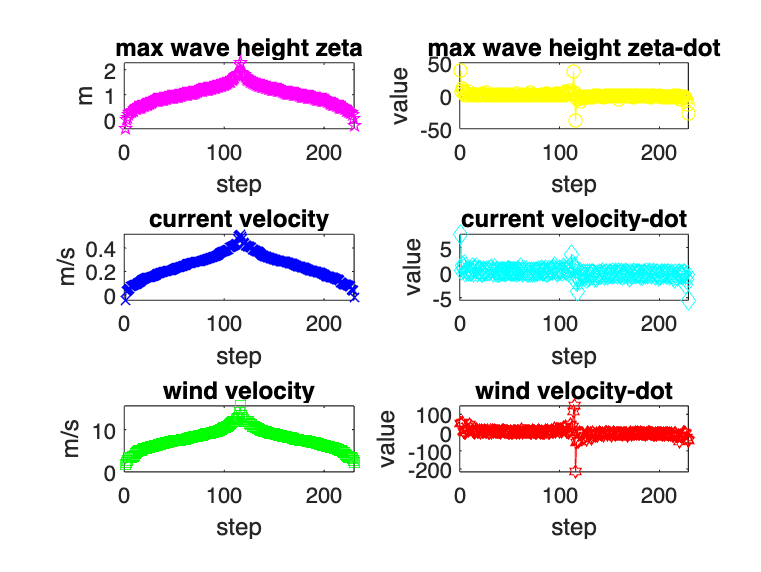


%disturbance model of wind wave current
figure(1)
subplot(321)
plot(zt,'p-m')
xlabel("step");ylabel("m")
title("max wave height zeta")
subplot(322)
plot(zt_dot,'o-y')
xlabel("step");ylabel("value")
title("max wave height zeta-dot")
subplot(323)
plot(cr,'x-b')
xlabel("step");ylabel("m/s")
title("current velocity")
subplot(324)
plot(cr_dot,'d-c')
xlabel("step");ylabel("value")
title("current velocity-dot")
subplot(325)
plot(wd,'s-g')
title("wind velocity")
xlabel("step");ylabel("m/s")
subplot(326)
plot(wd_dot,'h-r')
xlabel("step");ylabel("value")
title("wind velocity-dot")

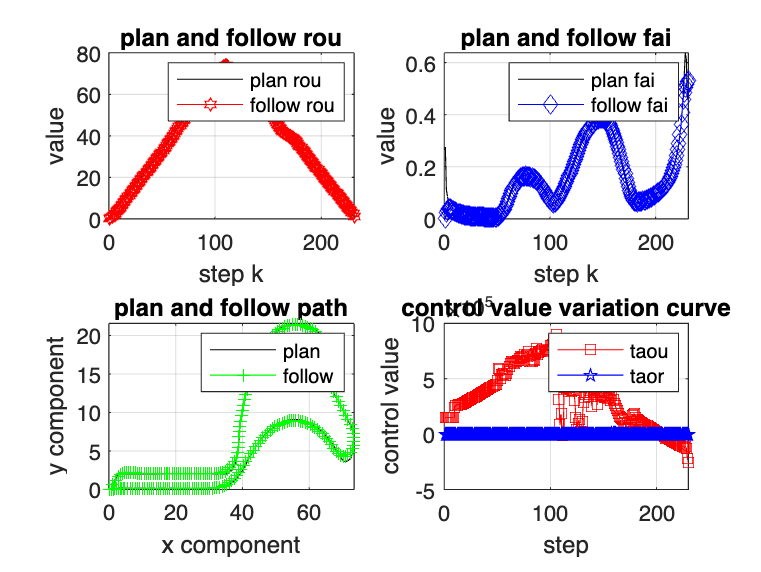

%disturbance model of wind wave current disturbance

% % MPC result
figure (2)
subplot(221)
K0=1:size(TJ,2);
K1=1:size(rou,2);
plot(K0,TJ(2,:),'k',K1,rou(1,:),'r-h');
title('plan and follow rou');xlabel('step k');ylabel('value');
grid on;legend('plan rou','follow rou');
subplot(222)
K4=1:size(TJ,2);
K5=1:size(pr,2);
plot(K4,TJ(1,:),'k',K5,pr(1,:),'b-d');
title('plan and follow fai');xlabel('step k');ylabel('value');
grid on;legend('plan fai','follow fai');
subplot(223)
plot(TJ(2,:).*cos(TJ(1,:)),TJ(2,:).*sin(TJ(1,:)),'-k');
hold on
% plot(roup(1,:).*cos(faip(1,:)),roup(1,:).*sin(faip(1,:)),'+-g');
plot(rou.*cos(pr),rou.*sin(pr),'+-g');
title('plan and follow path');xlabel('x component');ylabel('y component');
grid on;legend('plan','follow')
subplot(224)
K6=1:size(taouk,2);
K8=1:size(taork,2);
plot(K6,taouk(1,:),'r-s',K8,taork(1,:),'b-p');
title('control value variation curve');
xlabel('step');ylabel('control value');
grid on;legend('taou','taor')

% % MPC result


function [c,ceq] = taounonl(taou,aa,bb,cc)
    c = -(aa*taou^2+bb*taou+cc); %c<=0
    ceq = [];
end

% function [c,ceq] = taoucon(taou,a1,a2,a3,b1,b2,puc,pvc,Trr,p)
%      c= -Trr(1) + (b2 + b1*pvc)^2 + (a2 + a1*puc + a3*taou)^2;%<=0
%     ceq = []; 
% end
% 
% function [f,g] = funcwithgrad(taou,a1,a2,a3,b1,b2,puc,pvc,R,Q,Trr,p)  
%       f = R*taou^2 + Q*exp((Trr(1) - (b2 + b1*pvc)^2 - (a2 + a1*puc + a3*taou)^2));
%     if nargout > 1 % gradient required
%       g = 2*R*taou - 2*Q*a3*exp((Trr(1) - (b2 + b1*pvc)^2 - (a2 + a1*puc + a3*taou)^2))*(a2 + a1*puc + a3*taou);
%     end
% end
% 
% function [c,ceq] = taoucon2(taou,a1,a2,a3,b1,b2,puc,pvc,Trr,p)
%     c =  Trr(1) - (b2 + b1*pvc)^2 + (a2 + a1*puc + a3*taou)^2;%<=0
%     ceq = [];
% end
% 
% function [f,g] = funcwithgrad2(taou,a1,a2,a3,b1,b2,puc,pvc,R,Q,Trr,p)
%        f = R*taou^2 + Q*exp((-Trr(1) +(b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2));   
%     if nargout > 1 % gradient required
%        g = 2*R*taou + 2*Q*a3*exp((-Trr(1) +(b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2))*(a2 + a3*taou + a1*puc); 
%     end
% end
